**Preliminar analysis**

We now insert the data provided to carry on the experiemental lab

load('PSVdata.mat');
D=0.06;     %cilinder diameter
fs=50;      %time-step frequency
h=0.42;     %water height
hb=0.18;    %distance between cilinder and floor
Q=35*1e-3;  %volumetric flow rate in m^3/s
res=3040;   %image resolution
rho=998;    %water density
mu=0.001;   %viscosity
B=0.5;      %Width of the channel
steps=1499; %time steps

n=23;       %rows
m=30;       %columns

1: Ub bulk velocity and Red calculation 

Ub=Q/(B*h); %in m/s
Re= (Ub*D*rho)/mu  %Reynolds number

Re = 9980

2.1 Calculating (x0, y0) from reference image, both in meters and pixels

%position of (x0, y0) wrt (X, Y) ref system
%position in meters
x0=15.32*1e-2;
y0=9.5*1e-2; 

%position in pixels
x0_px=y0*res
y0_px=x0*res 

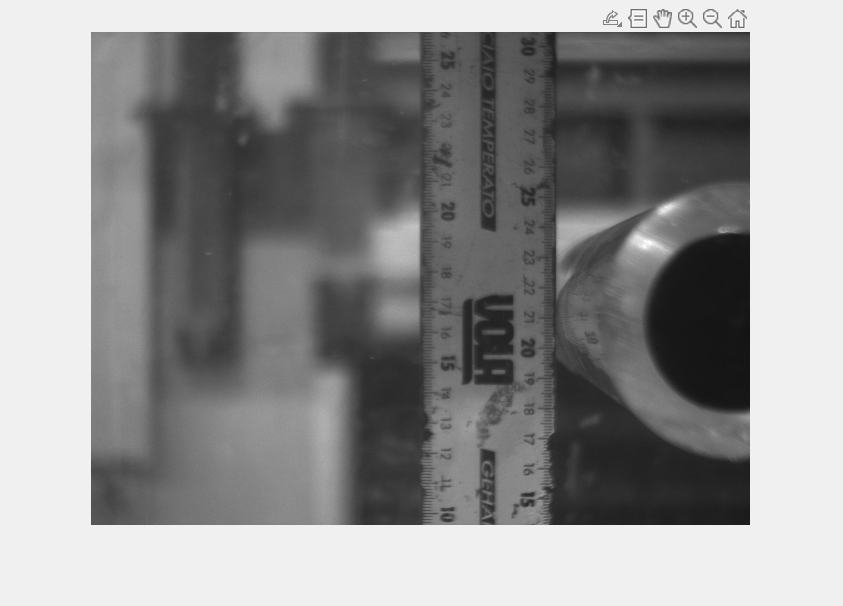

x0_px = 466

y0_px = 287

[x0_px, y0_px] = Find_pixel('ref_image.png')

x0 = x0_px / res

x0 = 0.1533

y0 = y0_px / res

y0 = 0.0944

2.2 Building Grid_x0m, Grid_y0m containing the coordinates of the centre cells in meters wrt to the new reference system in which (x0, y0) is the origin. Then create Grid_x0_D and Grid_y0_D dimentionless matrices.

Grid_Xm=Grid_Xpx./res; 
Grid_Ym=Grid_Ypx./res;

Grid_X0m=-(Grid_Xm-x0*ones(n, m));
Grid_Y0m=-(Grid_Ym-y0*ones(n, m));

%dimentionless
Grid_X0_D=Grid_X0m./D; 
Grid_Y0_D=Grid_Y0m./D;

2.3 Start from SXpx, and SYpx, building new matrixes Sx0m, and Sy0m, containing the displacements in meters according to the new coordinate system (x0, y0).

Sx0m=zeros(n, m, steps);
Sy0m=zeros(n, m, steps);

Sx0m= -(SXpx./res);
Sy0m= -(SYpx./res);

matrices of the “instantaneous” velocity field u0, v0 by considering that the displacements were measured during the exposition time 1/fs. Finally, making the two matrixes dimensionless by dividing by the bulk velocity Ub.

u0=zeros(n, m, steps);
v0=zeros(n, m, steps);
u0=Sx0m*fs;
v0=Sy0m*fs;
%dimentionless
u0_Ub=u0./Ub; 
v0_Ub=v0./Ub;

 **Analysis of the Reynolds-averaged flow field**

3 Calculating the Reynolds-averaged velocity field through matrixes U0_Ub and V0_Ub.

U0_Ub=nanmean(u0_Ub, 3);
V0_Ub=nanmean(v0_Ub, 3);

3.1 Color plot of the Reynolds-averaged velocity magnitude

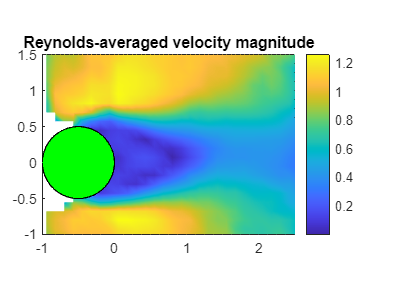

M=sqrt(V0_Ub.^2 + U0_Ub.^2);
figure();
pcolor(Grid_X0_D, Grid_Y0_D, M);
shading interp
colorbar
axis equal
title('Reynolds-averaged velocity magnitude');
ylim([-1, 1.5])
xlim([-1, 2.5])
hold on
rectangle('Position', [-1, -1/2, 1, 1], 'Curvature',[1, 1], 'FaceColor','g');

3.2 Vector map

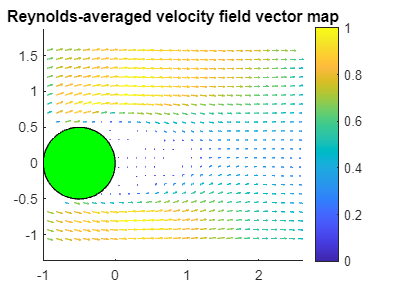

figure();
quiverC2D(Grid_X0_D, Grid_Y0_D, U0_Ub, V0_Ub, 1);
colorbar
axis equal
hold on
rectangle('Position', [-1, -1/2, 1, 1], 'Curvature',[1, 1], 'FaceColor','g');
title('Reynolds-averaged velocity field vector map');

3.3 Streamlines

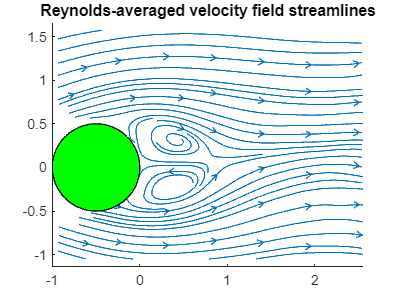

figure();
streamslice(Grid_X0_D, Grid_Y0_D, U0_Ub, V0_Ub, 'b-');
axis equal
hold on
rectangle('Position', [-1, -1/2, 1, 1], 'Curvature',[1, 1], 'FaceColor','g');
title('Reynolds-averaged velocity field streamlines');

3.4

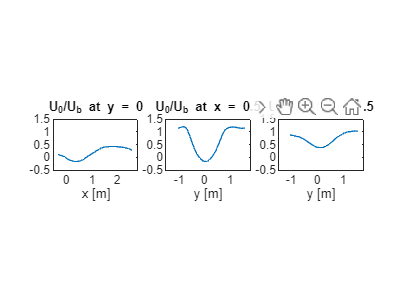

U0_0y = interp2(Grid_X0_D, Grid_Y0_D, U0_Ub, Grid_X0_D(1, :), 0);
figure()
subplot(1, 3, 1)
plot(Grid_X0_D(1, :), U0_0y)
axis equal
ylim([-0.5, 1.5])
xlim([-0.5, 2.8])
xlabel('x [m]')
title('U_0/U_b at y = 0')

U0_0y = interp2(Grid_X0_D, Grid_Y0_D, U0_Ub, 0.5, Grid_Y0_D(:, 1));
subplot(1, 3, 2)
plot(Grid_Y0_D(:, 1), U0_0y)
axis equal
ylim([-0.5, 1.5])
xlim([-1.5, 1.8])
xlabel('y [m]')
title('U_0/U_b at x = 0.5')

U0_0y = interp2(Grid_X0_D, Grid_Y0_D, U0_Ub, 1.5, Grid_Y0_D(:, 1));
subplot(1, 3, 3)
plot(Grid_Y0_D(:, 1), U0_0y)
axis equal
ylim([-0.5, 1.5])
xlim([-1.5, 1.8])
xlabel('y [m]')
title('U_0/U_b at x = 1.5')

4

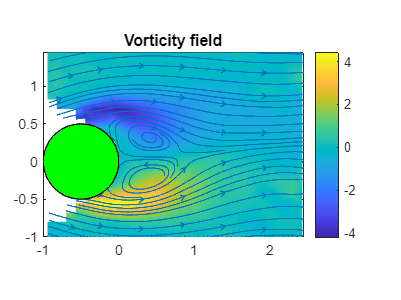

[vorticity, ~] = curl(Grid_X0_D, Grid_Y0_D, U0_Ub, V0_Ub);

figure();
pcolor(Grid_X0_D, Grid_Y0_D, vorticity);
shading interp
colorbar
ylim([-1, 1.45])
xlim([-1, 2.45])
axis tight
axis equal
title('Vorticity field');
hold on

%overlap streamlines and cylinder
streamslice(Grid_X0_D, Grid_Y0_D, U0_Ub, V0_Ub, 'r--');
ylim([-1, 1.45])
xlim([-1, 2.45])
rectangle('Position', [-1, -1/2, 1, 1], 'Curvature',[1, 1], 'FaceColor','g');
ylim([-1, 1.45])
xlim([-1, 2.45])
hold off

**5 Analysis of the dynamic evolution of the flow**

5.1 Plot the time history of the normalized vertical velocity v0/Ub in a point around the rear of the cylinder.

times = 0:(1/fs):(length(v0_Ub(1, 1, :))-1)/fs;

%Position near the rear stagnation point has 0<x<eps and y=0
eps = 0.1;
x_idx = find(Grid_X0_D(1, :) < eps & Grid_X0_D(1, :) > 0)

x_idx = 22

y_idx = find(abs(Grid_Y0_D(:, 1)) < eps/3*2) %to obtain a single value

y_idx = 15

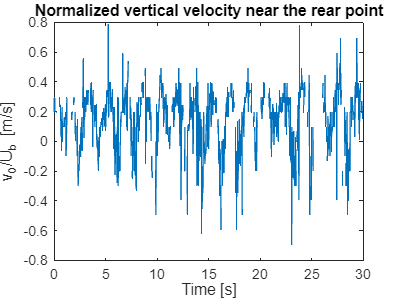

v0_Ub_point = squeeze(v0_Ub(x_idx, y_idx, :));
plot(times, v0_Ub_point)
xlabel('Time [s]')
ylabel('v_0/U_b [m/s]')
title('Normalized vertical velocity near the rear point')

5.2 Compute FFT of v0_Ub

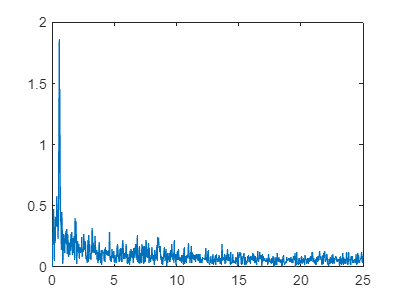

[freq, v0_Ub_fft] = fft_of_v0_Ub_velocity(v0_Ub_point,fs);
plot(freq, v0_Ub_fft)

%vortex shedding frequency
[~, peak_idx] = max(v0_Ub_fft);      
f_vortex = freq(peak_idx)

f_vortex = 0.5674

5.3 Strouhal number

Sr = f_vortex * D / Ub

Sr = 0.2043

1/sqrt(Re)    

ans = 0.0100

Hence the Sr in the reference is about 0.2, so the same...

5.4 Investigate sensiblity with respect to the chosen reference point: overlap frequency spectra of all the points of the domain

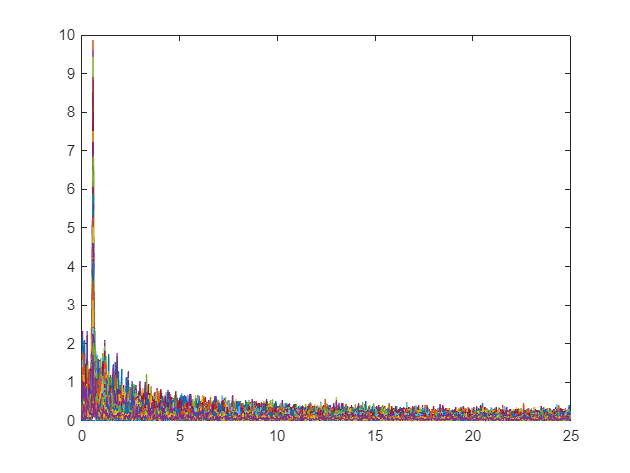

figure()
frequencies = zeros(n, m);
count = 0;
for i = 1:n
    for j = 1:m
        try
            vel = squeeze(v0_Ub(i, j, :));
            [f, v0_Ub_fft] = fft_of_v0_Ub_velocity(vel,fs);
            plot(f, v0_Ub_fft)
            hold on
            [~, peak_idx] = max(abs(v0_Ub_fft(2:end)));      
            f_v = f(peak_idx);
            frequencies(i, j) = f_v;
            count = count +1;
        catch
        end
    end
end

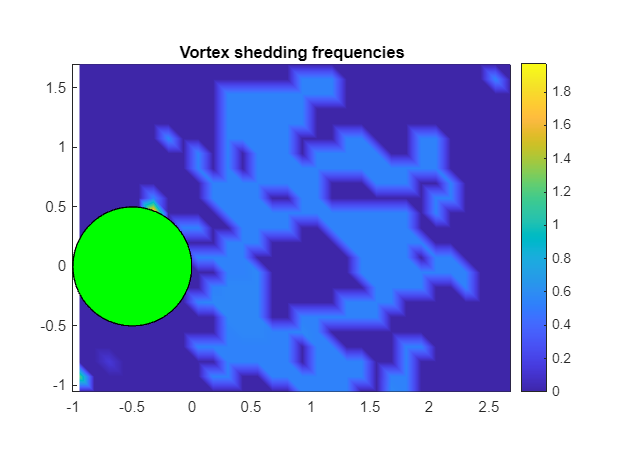

figure();
pcolor(Grid_X0_D, Grid_Y0_D, frequencies);
shading interp
colorbar
axis equal
title('Vortex shedding frequencies');
ylim([-1, 1.5])
xlim([-1, 2.5])
hold on
rectangle('Position', [-1, -1/2, 1, 1], 'Curvature',[1, 1], 'FaceColor','g');

It looks like the vortex frequencies all occur around the same frequence,

%This is the number of points where the fourier transform could be computed
count

count = 600

% This is the number of points where the vortex shedding freq. is !=0
sum(sum(frequencies ~= 0))

ans = 213

%Percentage of points where the transform is != 0
sum(sum(frequencies ~= 0))/(23*30)

ans = 0.3087

sum(sum(abs(frequencies(frequencies ~= 0)-f_vortex) > 0.09*f_vortex))

ans = 3

Indeed only 3 (over the 213 points) show a vortex frequency that has a relative distance from the previously computed f_vortex (in the reference point) of more than 10% 

5.5 Temporal moving average to u0_Ub, v0_Ub in the time window 0.2-0.25 T (T=1/f_vortex) using movmean(x, 'omitnan').

T = 1/f_vortex;
T_sample = 1/fs;
% We want to know how many samples k must be taken in the moving average for
% the window to be of the specified length
window = 0.225 * T;
k = ceil(window / T_sample)

k = 20

(Note that the average must be executed along the third dimension of the matrices)

Analyze time evolution of...

Velocity vector field

u_avg = movmean(u0_Ub, k, 3, 'omitnan');
v_avg = movmean(v0_Ub, k, 3, 'omitnan');

Velocity magnitude

mag = sqrt(u0_Ub.^2+v0_Ub.^2);
m_avg = movmean(mag, k, 3, 'omitnan');

Streamslices...

Vorticity field

vorticity_time = zeros(n, m, length(times));
for t = 1:length(times)
    [vorticity_time(:, :, t), ~] = curl(Grid_X0_D, Grid_Y0_D, u0_Ub(:, :, t), v0_Ub(:, :, t));
end
vorticity_mean = movmean(vorticity_time, k, 3, 'omitnan');

Plots

video_creation